## Gravador de audio

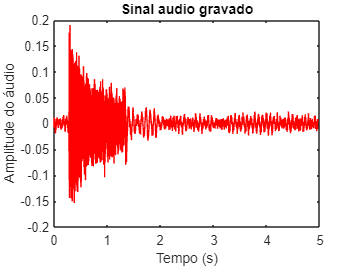

close all
clc

Tempo = 5; %5 segundos de gravação

FS = 8000; %Frequência de amostragem em 8 kHz
Nbits = 16; %sinal de 16 bits
Canais = 1; %1 = mono, 2 = stereo
r = audiorecorder(FS, Nbits, Canais); %preparar para gravar
record(r);
pause(Tempo);
stop(r);
Y = getaudiodata(r, 'double'); %guardar em uma variável double

%tocar áudio
p = audioplayer(Y,FS);
play(p)

N = length(Y);
t = 0:1/FS:(N-1)/FS;

figure
plot(t,Y,'r');
title("Sinal audio gravado");
xlabel('Tempo (s)');
ylabel('Amplitude do áudio');


save('audio_gravado.mat','Y', 'FS')


## AFINADOR

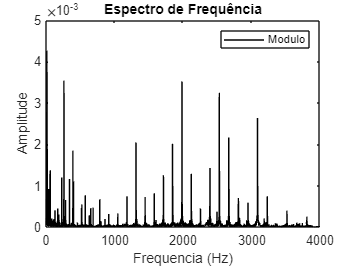

N = length(Y);
f = linspace(0,2*pi*(N-1)/N,N)*FS/(2*pi);
f = f(1:floor(N/2)+1);
P2 = abs(fft(Y))/length(Y);
P1 = P2(1:floor(N/2)+1);
P1(2:end) = 2 * P1(2:end);
frequencias = f;
espectro = P1;

figure
plot(frequencias,espectro,'k')
title("Espectro de Frequência")
xlabel("Frequencia (Hz)")
ylabel("Amplitude")
legend("Modulo")


[amplitude,indiceDominante] = max(espectro);

frequenciaDominante = frequencias(indiceDominante);

encontraNotaPredominante(frequenciaDominante);

Nota - C


function encontraNotaPredominante(frequenciaDominante)
    
    notas = [32 34 36 38 41 43 46 49 52 55 58 61];

    for n = 1:7
        
        if(frequenciaDominante < notas(1)+1*n)
            disp("Nota - C");
            break;
        elseif(frequenciaDominante < notas(2)+1*n)
            disp("Nota - C#");
            break;
        elseif(frequenciaDominante < notas(3)+1*n)
            disp("Nota - D");
            break;
        elseif(frequenciaDominante < notas(4)+1*n)
            disp("Nota - D#");
            break;
        elseif(frequenciaDominante < notas(5)+1*n)
            disp("Nota - E");
            break;
        elseif(frequenciaDominante < notas(6)+1*n)
            disp("Nota - F");
            break;
        elseif(frequenciaDominante < notas(7)+1*n)
            disp("Nota - F#");
            break;
        elseif(frequenciaDominante < notas(8)+1*n)
            disp("Nota - G");
            break;
        elseif(frequenciaDominante < notas(9)+1*n)
            disp("Nota - G#");
            break;
        elseif(frequenciaDominante < notas(10)+1*n)
            disp("Nota - A");
            break;
        elseif(frequenciaDominante < notas(11)+1*n)
            disp("Nota - A#");
            break;
        elseif(frequenciaDominante < notas(12)+1*n)
            disp("Nota - B");
            break;
        end

        notas = notas*2;

        if(n == 1)
            notas(1:4) = (notas(1:4)+1);
            notas(6) = notas(6)+1;
            notas(12) = notas(12)+1;
        elseif(n==2)
            notas(4) = notas(4)+1;
            notas(7) = notas(7)+1;
            notas(11) = notas(11)+1;
        elseif(n==3)
            notas(1:6) = notas(1:6)+1;
            notas(7) = notas(7)-0;5;
            notas(9) = notas(9)+1;
            notas(12) = notas(12)+1;
        elseif(n==4)
            notas(1) = notas(1)+1;
            notas(3) = notas(3)+1;
            notas(5) = notas(5)+1;
            notas(7) = notas(7)+1;
            notas(12) = notas(12)+1;
        end

    end

end